# **Explore 2-DOF Spring Mass Damper   - STEP responses        **

In this example we're going to study the two degree of freedom (dof)  mechanical system shown below:

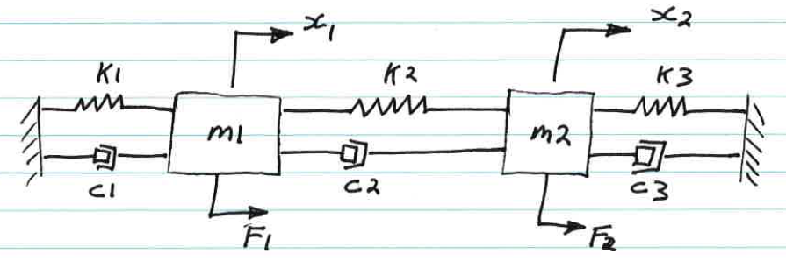 

In this tutorial we're going to look at the following subtopics:

$\qquad \bullet
$ apply Newton's laws to derive the system's dynamic equation of motion

$\qquad \bullet
$ derive the **ANALYTICAL** solution for an excitation case involving STEP functions

$\qquad \bullet $ solve **NUMERICALLY** the solution for the excitation case involving STEP functions

`Bradley Horton : 01-Mar-2016, bradley.horton@mathworks.com.au`

**Apply Newton's law:**

The free body diagram for this system is shown below:

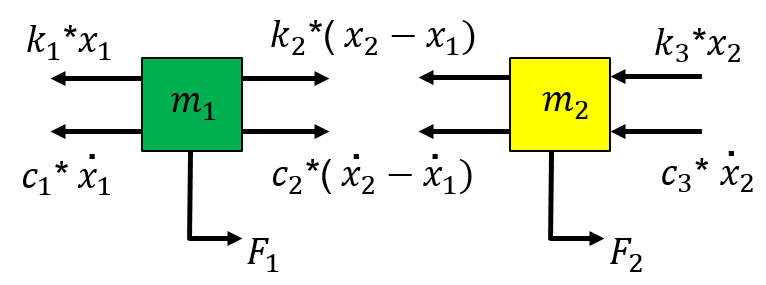

For the 1st mass we have:


$$m_1 \thinspace \ddot{x_1} = F_1 + k_2(x_2 - x_1) + c_2(\dot{x_2} - \dot{x_1}) - k_1x_1 - c_1 \dot{x_1}$$
 


$$m_1 \thinspace \ddot{x_1} = F_1  +  x_1(-k_2 + -k_1) +   x_2(k_2) +  \dot{x_1}(-c_2 + -c_1) +   \dot{x_2} (c_2) 
$$
 

For the 2nd mass we have:


$$m_2 \thinspace \ddot{x_2} = F_2 - k_2(x_2 - x_1) - c_2(\dot{x_2} - \dot{x_1}) - k_3x_2 - c_3 \dot{x_2}$$


 
$$m_2 \thinspace \ddot{x_2} = F_2  +  x_1(k_2) + x_2(-k_2 + -k_3) + \dot{x_1}(c_2) + \dot{x_2}(-c_2 + -c_3)$$


We can combine the two 2nd order ODEs into a matrix equation, ie:

$\pmatrix{
m_1 & 0 \cr
0 & m_2 \cr
}$$\times \pmatrix{
\ddot{x}_1 \cr
\ddot{x}_2 \cr
}$ + $\pmatrix{
(c_1 + c_2) & -c_2 \cr
-c_2 & (c_2+c_3) \cr
}$$\times \pmatrix{
\dot{x}_1 \cr
\dot{x}_2 \cr
}$ + $\pmatrix{
(k_1 + k_2) & -k_2 \cr
-k_2 & (k_2+k_3) \cr
}$$\times \pmatrix{
{x}_1 \cr
{x}_2 \cr
}$= $\pmatrix{
{F}_1 \cr
{F}_2 \cr
}$

which we can refer to as:   $M \ddot{X} + C\dot{X} + KX = F$where $X \in R^{n\times1}$

**Define the Mechanical system parameters:**

Note all parameters are in SI units, ie: *kg, N/m, N/(m/sec)*

params = bh_func_2dof_params()

params = struct with fields:
    m1: 10
    k1: 1000
    c1: 20
    m2: 1
    k2: 500
    c2: 50
    k3: 100
    c3: 10



m1 = params.m1 ;    m2 = params.m2 ; 
k1 = params.k1 ;    k2 = params.k2 ;    k3 = params.k3 ;
c1 = params.c1 ;    c2 = params.c2 ;    c3 = params.c3 ;


**Define the INITIAL conditions of the system:**

Let's consider the system with initial conditions of:

$\matrix{
\bullet \quad \dot{x}_1(0) = 0\cr
\bullet \quad \dot{x}_2(0) = 5\cr
\bullet \quad x_1(0) = 1\cr
\bullet \quad x_2(0) = -0.5\cr
}$   .

% define some INITIAL conditions for our system
init_x1dot = 0;
init_x2dot = 5;
init_x1    = 1;
init_x2    = -0.5;


## Define our system Excitation functions

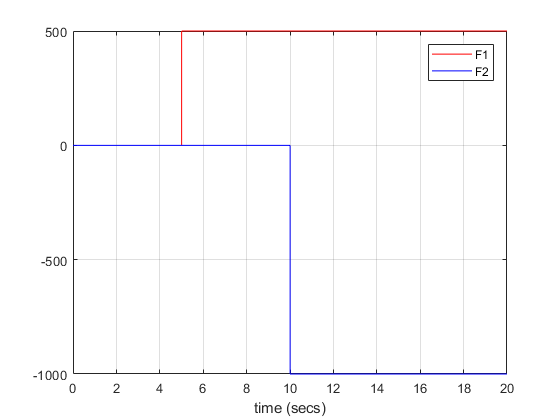

% here are our STEP function excitation forces 
syms t F1 F2

F1  =   500*heaviside(t-5);
F2  = -1000*heaviside(t-10);

% visualise them
figure
    fplot(F1, [-0.01, 20], '-r');  hold on
    fplot(F2, [-0.01, 20], '-b');  legend({'F1','F2'}); xlabel('time (secs)'); grid('on')

## Overview of finding Analytical solution:

When the damping matrix is a weighted sum of the mass and stiffness (eg: $C = \mu M + \beta K$) we can uncouple the entire damped equation of motion using a co-ordinate transformation consisting of the undamped modes - and this becomes a very straight forward exercise.

However, when the system damping is more general (ie: not Rayleigh damping), then it becomes more involved.  First we need to convert the system from it's 2nd order form into a new system of 1st order ODEs. And then we need to find a  a co-ordinate transformation which uncouples the new system.  

We start here:     $M \ddot{X} + C\dot{X} + KX = F$  where $X \in R^{n\times1}$

Mm_mat  = [m1, 0;
          0, m2];

Km_mat  = [(k1+k2), -k2;
           -k2,    (k2+k3) ];

Cm_mat  = [(c1+c2), -c2;
           -c2,    (c2+c3) ];

## STEP_1:  convert 2nd order system into 1st order system

The first stage is actually pretty simple.  We convert the 2nd order system into a new 1st order system.  We start here:     

                      $M \ddot{X} + C\dot{X} + KX = F$  where $X \in R^{n\times1}$

**STEP_1a.)**  We then create a new 1st order system:

                   $\pmatrix{
M & 0_{n\times n} \cr
0 & I_{n\times n} \cr
}$$\times \pmatrix{
\ddot{X} \cr
\dot{X} \cr
}$ + $\pmatrix{
C & K \cr
-I_{n \times n} & 0_{n \times n} \cr
}$$\times \pmatrix{
\dot{X} \cr
X \cr
}$ = $\pmatrix{
{F} \cr
0_{n \times 1} \cr
}$

**STEP_1b.)**  Rearranging gives:

                   $\pmatrix{
M & 0_{n\times n} \cr
0 & I_{n\times n} \cr
}$$\times \pmatrix{
\ddot{X} \cr
\dot{X} \cr
}$ = $\pmatrix{
-C & -K \cr
I_{n \times n} & 0_{n \times n} \cr
}$$\times \pmatrix{
\dot{X} \cr
X \cr
}$ + $\pmatrix{
{F} \cr
0_{n \times 1} \cr
}$

**STEP_1c.)**  Rearranging gives:

                   $\pmatrix{
\ddot{X} \cr
\dot{X} \cr
}$ =$\pmatrix{
M^{-1} & 0_{n \times n} \cr
0_{n \times n} & I_{n \times n}
} \times$ $\pmatrix{
-C & -K \cr
I_{n \times n} & 0_{n \times n} \cr
}$$\times \pmatrix{
\dot{X} \cr
X \cr
}$  +  $\pmatrix{
M^{-1} & 0_{n \times n} \cr
0_{n \times n} & I_{n \times n}
} \times$$\pmatrix{
{F} \cr
0_{n \times 1} \cr
}$

**STEP_1d.)**  Rearranging gives:

$\pmatrix{
\ddot{X} \cr
\dot{X} \cr
}$ = $\pmatrix{
-M^{-1}C & -M^{-1}K \cr
I_{n \times n} & 0_{n \times n} \cr
}$$\times \pmatrix{
\dot{X} \cr
X \cr
}$  +  $\pmatrix{
M^{-1}{F} \cr
0_{n \times 1} \cr
}$

which has the form:

                  $\dot{Z} = A \times Z + G$    where:  $Z =  \pmatrix{
\dot{X} \cr
X \cr
} \in R^{2n \times 1}$   and    $G = \pmatrix{
M^{-1}{F} \cr
0_{n \times 1} \cr
}$    and    $A = \pmatrix{
-M^{-1}{C} & -M^{-1}{K}\cr
I_{n \times n} & 0_{n \times n} \cr
}$

     
As_mat  = [-inv(Mm_mat)*Cm_mat,   -inv(Mm_mat)*Km_mat; 
                        eye(2),   zeros(2)  ];   
        

## STEP_2a:  determine an UNcoupling co-ordinate transformation

Consider the homogenous version of the system derived above:

-   
$$A \times Z = \dot{Z}  $$


and then look for a solution of the form  :  $Z =  v \times e^{\lambda \times t}$

This then leads to the general RIGHT hand eigenvalue problem:       

-    
$$A \times v = \lambda \times v$$


We can solve this exact problem using MATLAB's `eig()` function, ie:

`         [V,L] = eig(A)` $\Longrightarrow$  $A \times V = V \times L$   $\Longrightarrow$  $L = V^{-1} \times A \times V$

Note that in the above equation, $L$ is a diagonal matrix of our eigenvalues $\lambda$.  Before continuing it's worth pointing out that for MECHANICAL systems that are underdamped, we will have eigenvalues occurring in COMPLEX conjugate pairs, ie: $(\lambda_k, \bar{\lambda}_k)$and similarly eigenvectors occurring in complex conjugate pairs, ie: $(\vec{v_k}, \vec{\bar{v_k}})$.

So our uncoupling transformation will take the form:  $Z = V \times Q$

- 
$$\dot{Z} = A \times Z + G$$
   
$$\Longrightarrow$$
       
$$V \times \dot{Q} = A \times V \times Q \quad + \quad G$$


which finally gives us:

- 
$$\dot{Q} = (V^{-1} \times A \times V \times)\times Q \quad +  \quad (V^{-1} \times G)$$


- 
$$\dot{Q} = (L) \times Q \quad + \quad (V^{-1} \times G)$$


[V_mat, L_mat]   = eig(As_mat)

V_mat =    0.0842 + 0.0000i   0.7289 + 0.0000i   0.7289 + 0.0000i   0.0565 + 0.0000i
  -0.9963 + 0.0000i   0.6753 - 0.0530i   0.6753 + 0.0530i  -0.9952 + 0.0000i
  -0.0016 + 0.0000i  -0.0097 - 0.0721i  -0.0097 + 0.0721i  -0.0045 + 0.0000i
   0.0192 + 0.0000i  -0.0143 - 0.0660i  -0.0143 + 0.0660i   0.0798 + 0.0000i


L_mat =  -51.8371 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i  -1.3426 + 9.9343i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i  -1.3426 - 9.9343i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i -12.4778 + 0.0000i


% confirm the diagonalization transform
tmp = inv(V_mat) * As_mat * V_mat

tmp =  -51.8371 - 0.0000i  -0.0000 - 0.0000i   0.0000 + 0.0000i  -0.0000 - 0.0000i
  -0.0000 + 0.0000i  -1.3426 + 9.9343i  -0.0000 + 0.0000i  -0.0000 + 0.0000i
   0.0000 - 0.0000i  -0.0000 - 0.0000i  -1.3426 - 9.9343i  -0.0000 - 0.0000i
   0.0000 - 0.0000i  -0.0000 + 0.0000i  -0.0000 - 0.0000i -12.4778 + 0.0000i



% just make sure we remove any small imag terms
L_mat = diag(diag(L_mat));

## **So let's solve the systems ODEs:**

***PART_1:  prepare the system***

Recall some of the earlier equations:  

$Z =  \pmatrix{
\dot{X} \cr
X \cr
} \in R^{2n \times 1}$   and   $Z = V \times Q$     .

$\dot{Q} = (L) \times Q \quad + \quad (V^{-1} \times G)$ where $G = \pmatrix{
M^{-1}{F} \cr
0_{n \times 1} \cr
}$    .

% define some INITIAL conditions for our system
nZ_IC = [init_x1dot;
         init_x2dot;
         init_x1;
         init_x2 ];
     
% define the symbolic Q variables
syms q1(t) q2(t) q3(t) q4(t)

% from this moment onwards I want t to be regarded as REAL
assume(t, 'real');

Q = [q1, q2, q3, q4].' ;

Q_IC_EQ = Q(0) == inv(V_mat) * nZ_IC;

% define our excitations:
F = [F1, F2].' ;
G = [inv(Mm_mat)*F; zeros(2,1)];

% define our ODE
ODE_EQN = diff(Q) == L_mat*Q + inv(V_mat)*G;


## **So let's solve the systems ODEs:**

***PART_2:  solve the system***

% now let's solve our system
the_Q_sol = dsolve(ODE_EQN, Q_IC_EQ)

the_Q_sol = struct with fields:
    q2: [1×1 sym]
    q1: [1×1 sym]
    q3: [1×1 sym]
    q4: [1×1 sym]


% just assemble a vector of the solutions
Q_vec_sol = [the_Q_sol.q1;
             the_Q_sol.q2; 
             the_Q_sol.q3;
             the_Q_sol.q4;];
   
% so what does one look like ?
the_Q_sol.q3  

## **So let's solve the systems ODEs:**

***PART_3:  convert back to X***

Having solved the uncoupled system $\dot{Q} = (L) \times Q \quad + \quad (V^{-1} \times G)$, we now need to convert back to the $X(t)$ co-ordinates.  We do this via:

$\bullet \quad Z = V \times Q$       and 

$\bullet \quad Z =  \pmatrix{
\dot{X}_{n\times1} \cr
X_{n\times1} \cr
} $ .

*NOTE: we are expecting that or solution for *$X(t)$*will consist of only REAL terms.  The simplification engine however may not present the solution in this "clean" form.  We can confirm however that the imaginary component of *$X(t)$*is essentially zero. And then we can just ask for the REAL component of the solution.*

% convert from Z to X
Z_vec_sol = V_mat * Q_vec_sol;

% extract the solutions for x1(t) and x2(t)
x1_sol    = Z_vec_sol(3);
x2_sol    = Z_vec_sol(4);

x1_fh     = matlabFunction(x1_sol);
x2_fh     = matlabFunction(x2_sol);

x1_R = @(t) real(x1_fh(t));    x1_I = @(t) imag(x1_fh(t)); 
x2_R = @(t) real(x2_fh(t));    x2_I = @(t) imag(x2_fh(t)); 
 

So here's a plot of the positions $x1(t) $ and $x2(t) $.  

NOTE how the imaginary terms are effectively zero(as described above).

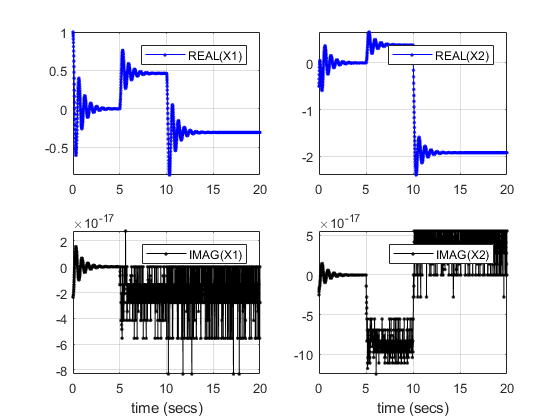

t_vec = 0:0.01:20;

% plot it
bh_plot_2dof_R_and_I( t_vec, ...
                      x1_R(t_vec),   x1_I(t_vec), ...
                      x2_R(t_vec),   x2_I(t_vec), ...
                      'X1', 'X2')

Similarly consider the velocities $\dot{x}_1(t)$ and $\dot{x}_2(t)$.

Again note that the imaginary component of the solution is effectively ZERO.

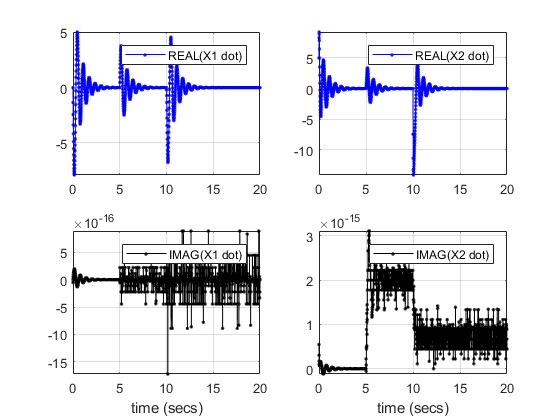

% extract the solutions for x1_dot(t) and x2_dot(t)
x1dot_sol = Z_vec_sol(1);
x2dot_sol = Z_vec_sol(2);

x1dot_fh  = matlabFunction(x1dot_sol);
x2dot_fh  = matlabFunction(x2dot_sol);

x1dot_R = @(t) real(x1dot_fh(t));    x1dot_I = @(t) imag(x1dot_fh(t)); 
x2dot_R = @(t) real(x2dot_fh(t));    x2dot_I = @(t) imag(x2dot_fh(t));

t_vec = 0:0.01:20;

% plot it
bh_plot_2dof_R_and_I( t_vec, ...
                      x1dot_R(t_vec),   x1dot_I(t_vec), ...
                      x2dot_R(t_vec),   x2dot_I(t_vec), ...
                      'X1 dot', 'X2 dot')

**So let's summarise o****ur ANALYTICAL solution:**

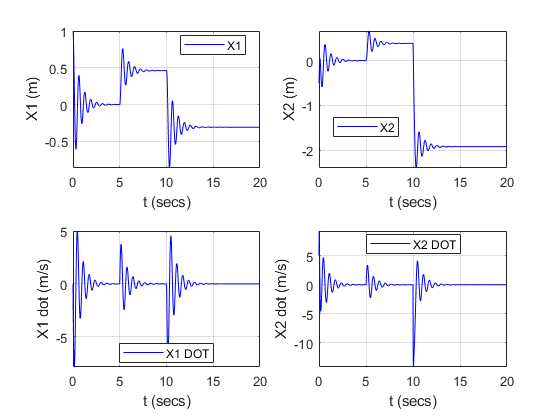

% plot the responses
  bh_plot_2dof_response( t_vec, x1_R(t_vec),    ...
                                x2_R(t_vec),    ...
                                x1dot_R(t_vec), ...
                                x2dot_R(t_vec), ...
                                '-b'); 

# Numerical solution:

So far we've looked at finding an analytical solution to the mechanical system. An alternate approach is to solve the problem numerically. This numerical approach is extremely attractive when an analytical solution becomes difficult and/or impossible to derive.  At the heart of this approach are MATLAB's ODE solver suit - MATLAB has many ODE solver algorithms.  A good general purpose solver is the MATLAB function `ode45()` .

These numeric ODE solvers require you to package your problem into a 1st order form. We've already seen how to do this for a Mechanical system ,ie:

                      $\pmatrix{
\ddot{X} \cr
\dot{X} \cr
}$ = $\pmatrix{
-M^{-1}C & -M^{-1}K \cr
I_{n \times n} & 0_{n \times n} \cr
}$$\times \pmatrix{
\dot{X} \cr
X \cr
}$  +  $\pmatrix{
M^{-1}{F} \cr
0_{n \times 1} \cr
}$

which has the form:

                  $\dot{Z} = A \times Z + G$    where:  $Z =  \pmatrix{
\dot{X} \cr
X \cr
} \in R^{2n \times 1}$   and    $G = \pmatrix{
M^{-1}{F} \cr
0_{n \times 1} \cr
}$     and    $A = \pmatrix{
-M^{-1}{C} & -M^{-1}{K}\cr
I_{n \times n} & 0_{n \times n} \cr
}$

So let's look at the example we solved previously:

% Define your INITIAL conditions
z_init = [init_x1dot;
          init_x2dot;
          init_x1;
          init_x2 ];

% define the system EXCITATION functions
                   % F1                   F2         
Fh_col    = @(t) [(500*heaviside(t-5)); (-1000*heaviside(t-10)) ];

% define the 1st order system to solve
MY_SYSTEM = @(t, z) bh_mech_to_1st_order(Mm_mat, Km_mat, Cm_mat, Fh_col,t,z);

% Define some ODE solver settings
t_span     = [0 20];
my_options = odeset('RelTol', 1e-7, 'AbsTol', 1e-7);

% use ODE45 to numerically solve your system
%[T,Y] = solver(odefun,   tspan,  z0,     options)
[T,Z]  = ode45(MY_SYSTEM, t_span, z_init, my_options);

## Plot the NUMERIC solution:

X1_dot = Z(:,1); 
X2_dot = Z(:,2);  
X1     = Z(:,3);  
X2     = Z(:,4);

Plot the NUMERIC responses:

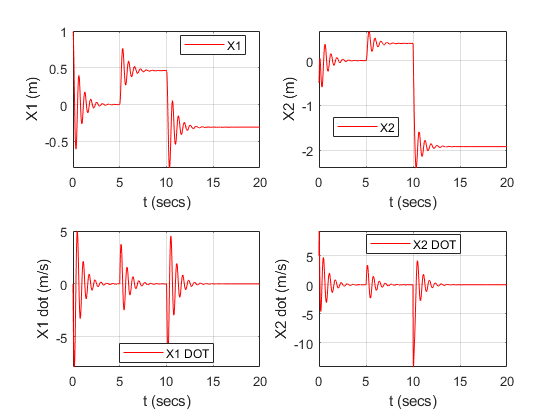


  bh_plot_2dof_response( T, X1,     ...
                            X2,     ...
                            X1_dot, ...
                            X2_dot, ...
                            '-r');

# **Compare ANALYTICAL versus Numeric solutions**

**We 'll ****just do a visual comparison for now:**

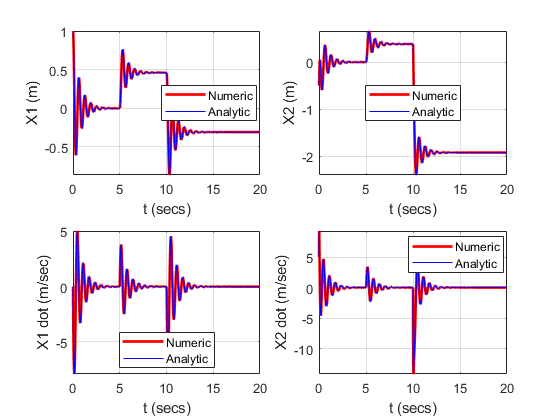

figure;
subplot(2,2,1);
   plot(T,X1,'-r', 'Linewidth', 2);      hold on
   plot(t_vec,x1_R(t_vec),'-b');         bh_annotate_2dof_compare( gca, 't (secs)', 'X1 (m)')
   %----------------------------------------------------------------------- 
subplot(2,2,2);
   plot(T,X2,'-r', 'Linewidth', 2);      hold on
   plot(t_vec,x2_R(t_vec),'-b');         bh_annotate_2dof_compare( gca, 't (secs)', 'X2 (m)') 
   %----------------------------------------------------------------------- 
subplot(2,2,3);
   plot(T,X1_dot,'-r', 'Linewidth', 2);  hold on
   plot(t_vec, x1dot_R(t_vec), '-b');    bh_annotate_2dof_compare( gca, 't (secs)', 'X1 dot (m/sec)') 
   %----------------------------------------------------------------------- 
subplot(2,2,4);
   plot(T,X2_dot,'-r', 'Linewidth', 2);  hold on
   plot(t_vec, x2dot_R(t_vec),'-b');     bh_annotate_2dof_compare( gca, 't (secs)', 'X2 dot (m/sec)')        

And what about a plot of the errors ?

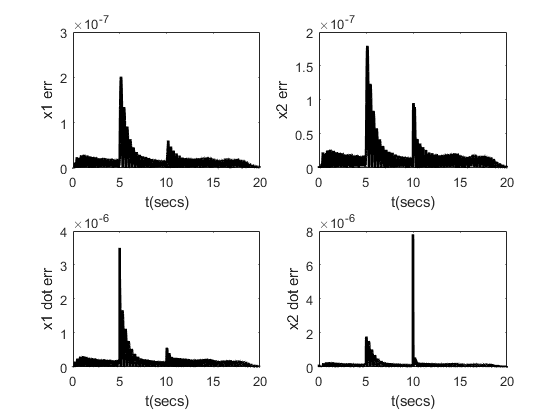

err_X1     = abs( X1 - x1_R(T) );
err_X2     = abs( X2 - x2_R(T) );
err_X1_dot = abs( X1_dot - x1dot_R(T) );
err_X2_dot = abs( X2_dot - x2dot_R(T) );

figure;
subplot(2,2,1); plot(T,err_X1,    '-k', 'Linewidth', 2); ylabel('x1 err');     xlabel('t(secs)');
subplot(2,2,2); plot(T,err_X2,    '-k', 'Linewidth', 2); ylabel('x2 err');     xlabel('t(secs)');
subplot(2,2,3); plot(T,err_X1_dot,'-k', 'Linewidth', 2); ylabel('x1 dot err'); xlabel('t(secs)');
subplot(2,2,4); plot(T,err_X2_dot,'-k', 'Linewidth', 2); ylabel('x2 dot err'); xlabel('t(secs)');

# Next steps ?

If you liked this tutorial why not have have a quick look at SIMULINK.

What is Simulink ? - good questions. Simulink is a block diagram modelling and simulation tool. So? So rather than writing lines of code, you construct mathematical models using block diagrams. A great example to look at is the Simulink model **bh_2dof_ODE_model.slx.**

And finally, why not look at an alternate way of using Simulink to model dynamic systems - it's called Simscape.  In Simscape you're still using the Simulink modelling environment, but rather than your focus being the implmentation of mathematical equations, your focus is instead on assembling a model that "physically" represents your system, eg: instead of using integrator blocks to implement ODEs in simscape you would use a spring block, a damper block, a mass block, etc.  Check it out in the following model **bh_2dof_simscape_model.slx** .